$F_c$ - driving force - $[N]$

$\eta_g$ - gearbox efficiency - $[-]$

$K_g$ - gear ratio - $[-]$

$r_{mp}$ - motor pinion radius (prumer pastorku) - $[m]$


$$F_c = \frac{\eta_g K_g \tau_M}{r_{mp}
}$$


$M_c$- mass of the cart - $[kg]$

$x_C$ - cart position - $[m]$

$B_{eq}$ - equivalent viscous damping coefficient - $[\frac{N m\; s}{rad}]$ 

eta_g = 0.9 %gearbox efficiency

eta_g = 0.9000

K_g = 3.71 %gearbox gear ratio

K_g = 3.7100

k_t = 7.68e-3 %motor current-torque constant

k_t = 0.0077

k_m = 7.68e-3 %motor back-emf constant

k_m = 0.0077

R_m = 2.6 %motor armature resistance

R_m = 2.6000

r_mp = 6.35e-3 %motor pinion radius (prumer pastorku)

r_mp = 0.0064

eta_m = 0.69 %motor efficiency

eta_m = 0.6900

A_m = eta_g * K_g * eta_m * k_t / r_mp / R_m %actuator gain

A_m = 1.0717

J_p = 1.2e-3 %moment of inertia about CoM, medium length pendulum

J_p = 0.0012

L_p = 0.3365 %full length of the pendulum

L_p = 0.3365

l_p = L_p/2

l_p = 0.1683

M_p = 0.127 %pendulum mass

M_p = 0.1270

%J_p = J_pCoM + M_p * l_p^2
M_c = 0.38 %cart mass

M_c = 0.3800

J_m = 3.9e-7 %motor moment of inertia

J_m = 3.9000e-07

J_eq = M_c + eta_g*K_g^2*J_m/r_mp^2

J_eq = 0.4998

B_eq = 4.3 %equivalent viscous damping coefficient (cart)

B_eq = 4.3000

B_p = 0.0024 %equivalent viscous damping coefficient (pendulum)

B_p = 0.0024

g = 9.81

g = 9.8100


syms x_c(t) alpha(t) V_m u

%sila pusobici na cart
F_c = (eta_g*K_g*k_t/R_m/r_mp)*(-K_g*k_m*diff(x_c,t)/r_mp + eta_m*V_m) %2.11 LinPendulumGantry

$$F\_c(t) = \frac{482657913448593747\,V_{m}}{450359962737049600}-\frac{7785481995192533919\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000}$$


%rovnice systemu (2.9 a 2.10 v LinearPendulumGantry)
disp("2.9 a 2.10")

2.9 a 2.10


ode1 = (J_eq+M_p)*diff(x_c,t,2) + M_p*l_p*cos(alpha)*diff(alpha,t,2) - M_p*l_p*sin(alpha)*diff(alpha,t)^2 == F_c - B_eq*diff(x_c,t)

$$ode1(t) = \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{4503599627370496}=\frac{482657913448593747\,V_{m}}{450359962737049600}-\frac{12589028394620322719\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000}$$

ode2 = M_p*l_p*cos(alpha)*diff(x_c,t,2) + (J_p+M_p*l_p^2)*diff(alpha,t,2) + M_p*l_p*g*sin(alpha) == -B_p*diff(alpha,t)

$$ode2(t) = \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)}{288230376151711744}+\frac{5528401504798809\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250}$$


ode1 = subs(ode1, V_m, u);
ode2 = subs(ode2, V_m, u);

odes = [ode1, ode2]

$$odes(t) = \begin{array}{l} \left(\begin{array}{cc} \frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{2}}{288230376151711744}-\frac{6158834620015739\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{288230376151711744}+\frac{2822919194634723\,\sigma_{1}}{4503599627370496}=\frac{482657913448593747\,u}{450359962737049600}-\frac{12589028394620322719\,\frac{\partial }{\partial t}x_{c}\left(t\right)}{1117103813820416000} & \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}}{288230376151711744}+\frac{5528401504798809\,\sigma_{2}}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right) \end{array}$$

%odes = simplify(odes)


[V, S] = odeToVectorField(odes);

S

$$S = \left(\begin{array}{c} \alpha \\ \mathrm{Dalpha}\\ x_{c}\\ {\mathrm{Dx}}_{c} \end{array}\right)$$

order = [3 1 4 2]

order =      3     1     4     2


S = columnMatrixRearrange(S, order)

$$S = \left(\begin{array}{c} x_{c}\\ \alpha \\ {\mathrm{Dx}}_{c}\\ \mathrm{Dalpha} \end{array}\right)$$

V = columnMatrixRearrange(V, order)

$$V = \begin{array}{l} \left(\begin{array}{c} Y_{4}\\ Y_{2}\\ -\frac{2702600527374972243398096421103798125\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}+1352674373017690692752698152207777792\,\cos\left(Y_{1}\right)\,Y_{2}+135550998138622756325414663090724008400\,u+118143497021674315858827754898758000000\,\cos\left(Y_{1}\right)\,\sin\left(Y_{1}\right)-1425350728105450021100815047615317422080\,Y_{4}}{317500\,\sigma_{1}}\\ \frac{3010792482713412718070883237467104375\,\cos\left(Y_{1}\right)\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}+9920033739558007695949399027146031104\,Y_{2}+866422473835876089577635639302496000000\,\sin\left(Y_{1}\right)-1587891075259367506641974498084338503680\,\cos\left(Y_{1}\right)\,Y_{4}+151008601562165373061735538694788876400\,u\,\cos\left(Y_{1}\right)}{79375\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=37931243876704412196168607716121\,{\cos\left(Y_{1}\right)}^{2}-249699691576704713964325767118512 \end{array}$$

fh_tmp = matlabFunction(V, 'vars', {'t', 'Y', 'u'})

fh_tmp = function_handle with value:
    @(t,Y,u)[Y(4);Y(2);((u.*1.355509981386228e+38+cos(Y(1)).*Y(2).*1.352674373017691e+36+sin(Y(1)).*Y(2).^2.*2.702600527374972e+36+cos(Y(1)).*sin(Y(1)).*1.181434970216743e+38-Y(4).*1.42535072810545e+39).*(-3.149606299212598e-6))./(cos(Y(1)).^2.*3.793124387670441e+31-2.496996915767047e+32);(sin(Y(1)).*8.664224738358761e+38-cos(Y(1)).*Y(4).*1.587891075259368e+39+Y(2).*9.920033739558008e+36+u.*cos(Y(1)).*1.510086015621654e+38+cos(Y(1)).*sin(Y(1)).*Y(2).^2.*3.010792482713413e+36)./(cos(Y(1)).^2.*3.010792482713413e+36-1.981991301890094e+37)]


x = sym('x', [1 4]);
x = [x(order(end)), x(order(end-1)), x(order(end-2)), x(order(end-3))]

$$x = \left(\begin{array}{cccc} x_{2} & x_{4} & x_{1} & x_{3} \end{array}\right)$$

V = fh_tmp(t, x, u)

$$V = \left(\begin{array}{c} x_{3}\\ x_{4}\\ -\frac{8512127645275501541815007773881\,\sin\left(x_{2}\right)\,{x_{4}}^{2}+\frac{17041566904159886105622643074519\,\cos\left(x_{2}\right)\,x_{4}}{4}+426932277601961545856715769859664\,u-4489293631828188876214630014998784\,x_{3}+372105502430470173291911241223008\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)}{37931243876704411422902005530624\,{\cos\left(x_{2}\right)}^{2}-249699691576704686201012758773760}\\ \frac{3010792482713413213644005406647779328\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)\,{x_{4}}^{2}+9920033739558008074107652538191839232\,x_{4}+866422473835876147007917881376536264704\,\sin\left(x_{2}\right)+151008601562165394046364202922886037504\,u\,\cos\left(x_{2}\right)-1587891075259367951312972396086465396736\,x_{3}\,\cos\left(x_{2}\right)}{3010792482713413213644005406647779328\,{\cos\left(x_{2}\right)}^{2}-19819913018900939397566115787791400960} \end{array}\right)$$

x = sym('x', [1 4]);

A_sym = jacobian(V, x);
B_sym = jacobian(V, u);

disp([transpose(x)  S])

$$\left(\begin{array}{cc} x_{1} & x_{c}\\ x_{2} & \alpha \\ x_{3} & {\mathrm{Dx}}_{c}\\ x_{4} & \mathrm{Dalpha} \end{array}\right)$$

x_operating = [0, 0, 0, 0];
A = subs(A_sym, [x, u], [x_operating, 0]);
B = subs(B_sym, [x, u], [x_operating, 0]);

A = double(A)

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    1.7571  -21.1991    0.0201
         0  -51.5448   94.4660   -0.5902


B = double(B)

B =          0
         0
    2.0160
   -8.9837


C = eye(4)

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D = [0; 0; 0; 0]

D =      0
     0
     0
     0


fh_tmp = matlabFunction(V, 'vars', {'t', 'x1', 'x2', 'x3', 'x4', 'u'})

fh_tmp = function_handle with value:
    @(t,x1,x2,x3,x4,u)[x3;x4;-(u.*4.269322776019615e+32-x3.*4.489293631828189e+33+x4.^2.*sin(x2).*8.512127645275502e+30+cos(x2).*sin(x2).*3.721055024304702e+32+x4.*cos(x2).*4.260391726039972e+30)./(cos(x2).^2.*3.793124387670441e+31-2.496996915767047e+32);(x4.*9.920033739558008e+36+sin(x2).*8.664224738358761e+38+u.*cos(x2).*1.510086015621654e+38-x3.*cos(x2).*1.587891075259368e+39+x4.^2.*cos(x2).*sin(x2).*3.010792482713413e+36)./(cos(x2).^2.*3.010792482713413e+36-1.981991301890094e+37)]


string_fh = char(fh_tmp);
string_fh = strrep(string_fh, 'x1', 'Y(1)');
string_fh = strrep(string_fh, 'x2', 'Y(2)');
string_fh = strrep(string_fh, 'x3', 'Y(3)');
string_fh = strrep(string_fh, 'x4', 'Y(4)');
string_fh = strrep(string_fh, 'x2', 'Y(2)');
string_fh = strrep(string_fh, '@(t,Y(1),Y(2),Y(3),Y(4),u)', '@(t, Y, u)')

string_fh = '@(t, Y, u)[Y(3);Y(4);-(u.*4.269322776019615e+32-Y(3).*4.489293631828189e+33+Y(4).^2.*sin(Y(2)).*8.512127645275502e+30+cos(Y(2)).*sin(Y(2)).*3.721055024304702e+32+Y(4).*cos(Y(2)).*4.260391726039972e+30)./(cos(Y(2)).^2.*3.793124387670441e+31-2.496996915767047e+32);(Y(4).*9.920033739558008e+36+sin(Y(2)).*8.664224738358761e+38+u.*cos(Y(2)).*1.510086015621654e+38-Y(3).*cos(Y(2)).*1.587891075259368e+39+Y(4).^2.*cos(Y(2)).*sin(Y(2)).*3.010792482713413e+36)./(cos(Y(2)).^2.*3.010792482713413e+36-1.981991301890094e+37)]'

fh = eval(string_fh)

fh = function_handle with value:
    @(t,Y,u)[Y(3);Y(4);-(u.*4.269322776019615e+32-Y(3).*4.489293631828189e+33+Y(4).^2.*sin(Y(2)).*8.512127645275502e+30+cos(Y(2)).*sin(Y(2)).*3.721055024304702e+32+Y(4).*cos(Y(2)).*4.260391726039972e+30)./(cos(Y(2)).^2.*3.793124387670441e+31-2.496996915767047e+32);(Y(4).*9.920033739558008e+36+sin(Y(2)).*8.664224738358761e+38+u.*cos(Y(2)).*1.510086015621654e+38-Y(3).*cos(Y(2)).*1.587891075259368e+39+Y(4).^2.*cos(Y(2)).*sin(Y(2)).*3.010792482713413e+36)./(cos(Y(2)).^2.*3.010792482713413e+36-1.981991301890094e+37)]




linearSystem = ss(A,B,C,D);

disp("Poles:")

Poles:


eigs(A)

ans =  -20.9347 + 0.0000i
  -0.4272 + 6.6396i
  -0.4272 - 6.6396i
   0.0000 + 0.0000i



disp("Poles of a subsystem without x_C:")

Poles of a subsystem without x_C:


A_sub = A;
A_sub(1,:) = []; %check if x_c is at index 3 in vector S
A_sub(:,1) = [];
eigs(A_sub)

ans =  -20.9347 + 0.0000i
  -0.4272 + 6.6396i
  -0.4272 - 6.6396i


initialCondition = [pi/4, 0, 0, 0] %xc alpha dxc dalpha

initialCondition =     0.7854         0         0         0


simulationTime = 20;

tspan = 0:0.001:20

tspan =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


solutionNon = ode45(@(t, Y) fh(t, Y, -Kr_lqr*(Y-[pi; 0; 1; 0])), 0:0.01:20, initialCondition);
[y, t, x] = initial(linearSystem, initialCondition, simulationTime);
solutionLinear = struct;
solutionLinear.t = t;
solutionLinear.x = x;

Vsub = V(2:4);
Vsub = subs(Vsub, u, 0)

$$Vsub = \left(\begin{array}{c} x_{4}\\ -\frac{8512127645275501541815007773881\,\sin\left(x_{2}\right)\,{x_{4}}^{2}+\frac{17041566904159886105622643074519\,\cos\left(x_{2}\right)\,x_{4}}{4}-4489293631828188876214630014998784\,x_{3}+372105502430470173291911241223008\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)}{37931243876704411422902005530624\,{\cos\left(x_{2}\right)}^{2}-249699691576704686201012758773760}\\ \frac{3010792482713413213644005406647779328\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)\,{x_{4}}^{2}+9920033739558008074107652538191839232\,x_{4}+866422473835876147007917881376536264704\,\sin\left(x_{2}\right)-1587891075259367951312972396086465396736\,x_{3}\,\cos\left(x_{2}\right)}{3010792482713413213644005406647779328\,{\cos\left(x_{2}\right)}^{2}-19819913018900939397566115787791400960} \end{array}\right)$$

fhsub = matlabFunction(Vsub, 'vars', {'x2', 'x3', 'x4', 't'})

fhsub = function_handle with value:
    @(x2,x3,x4,t)[x4;-(x3.*-4.489293631828189e+33+x4.^2.*sin(x2).*8.512127645275502e+30+cos(x2).*sin(x2).*3.721055024304702e+32+x4.*cos(x2).*4.260391726039972e+30)./(cos(x2).^2.*3.793124387670441e+31-2.496996915767047e+32);(x4.*9.920033739558008e+36+sin(x2).*8.664224738358761e+38-x3.*cos(x2).*1.587891075259368e+39+x4.^2.*cos(x2).*sin(x2).*3.010792482713413e+36)./(cos(x2).^2.*3.010792482713413e+36-1.981991301890094e+37)]


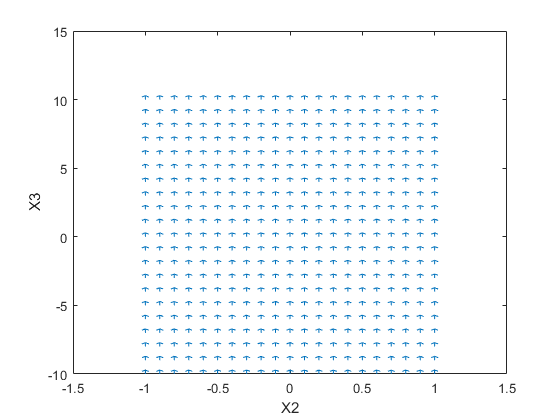


%[X2, X3, X4] = meshgrid(-1:0.1:1, -10:1:10, -10:1:10);
[X2, X3] = meshgrid(-1:0.1:1, -10:1:10);

n1=length(X2);
n2=length(X3);
%n3=length(X4);
DX1=zeros(n1,n2);
DX2=zeros(n1,n2);
%DX3=zeros(n1,n2,n3);
for i=1:n1
  for j=1:n2
      %for k=1:n3
        %DX = fhsub(X2(i),X3(j),X4(k), t);
        DX = fhsub(X2(i),X3(j), t);
        DX1(i,j) = DX(1);
        DX2(i,j) = DX(2);
        %DX3(i,j,k) = DX(3);
      %end
  end
end

quiver(X2,X3,DX1,DX2,0.3)
xlabel('X2')
ylabel('X3')